# CA1 Q3

This file is not a report. I have written details briefly for you to review quickly and give suggestions. However, all the sentences and formulas included can be easily moved into Word documents. (double-click the formulas to see Latex code)

## Part a)

I have checked the frames, and the frames and D-H table are all correct except that the graph of $O_2$ seems a bit strange.

The question has mentioned that the coordinates of point A is WRT $O_3$-$x_3y_3z_3$, but in this case the coordinate will be fixed and there will be no linear or angular velocity. Therefore, the following has derived the Jacobian that relates the position and orientation (or linear and angular velocity) of point A WRT $O_0$-$x_0y_0z_0$.

One way to compute is to first find the Jacobian that relates the joint rates and the velocities of $O_3$, and then transform to those of point A. This can be done in two ways.

The first is quite analytical. First compute the $T$ matrices as follows:

t = sym('theta', [3, 1]) % joint displacements

$$t = \left(\begin{array}{c} \theta_{1}\\ \theta_{2}\\ \theta_{3} \end{array}\right)$$

Define the DH table, where the unit has been changed to meter.

DH_table = [-pi/2 0 0.4 t(1)
             pi/2 0   0 t(2)
                0 0 0.1 t(3)]

$$DH\_table = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & \frac{2}{5} & \theta_{1}\\ \frac{\pi }{2} & 0 & 0 & \theta_{2}\\ 0 & 0 & \frac{1}{10} & \theta_{3} \end{array}\right)$$

A = cell(1, 3); % A{i} means $^{i-1}_{i}A$
for i = 1: 3
    P = DH_table(i, :);
    A{i} = [cos(P(4)) -sin(P(4))*cos(P(1))  sin(P(4))*sin(P(1)) P(2)*cos(P(4))
            sin(P(4))  cos(P(4))*cos(P(1)) -cos(P(4))*sin(P(1)) P(2)*sin(P(4))
                    0            sin(P(1))            cos(P(1))           P(3)
                    0                    0                    0              1];
    fprintf('A{%i} =', i); disp(A{i})
end

A{1} =

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & \frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A{2} =

$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & 0 & \sin\left(\theta_{2}\right) & 0\\ \sin\left(\theta_{2}\right) & 0 & -\cos\left(\theta_{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A{3} =

$$\left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & 0\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{1}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Compute $T$ using the rule $^0_iT=^0_{i-1}T^{i-1}_iA$:

T = cell(1, 4); % T{i} means $^{0}_{i-1}T$
for i = 1: 4
    T{i} = sym(eye(4)); % $^0_0T$ is an identity
    if i > 1
        T{i} = T{i-1} * A{i-1};
    end
    fprintf('T{%i} =', i); disp(T{i})
end

T{1} =

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T{2} =

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & \frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T{3} =

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 0\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 0\\ -\sin\left(\theta_{2}\right) & 0 & \cos\left(\theta_{2}\right) & \frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T{4} =

$$\begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \sigma_{2} & \frac{\sigma_{2}}{10}\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \sigma_{1} & \frac{\sigma_{1}}{10}\\ -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{2}\right) & \frac{\cos\left(\theta_{2}\right)}{10}+\frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

Then compute the Jacobian using the formula for rotary joints:

J = sym(zeros(6, 3));
JL = cell(1, 3); JA = cell(1, 3); % JL{i} is just $J_{Li}$; same for JA{i}
for i = 1: 3
    JL{i} = cross(T{i}(1:3, 3), T{4}(1:3, 4)-T{i}(1:3, 4));
    JL{i} = simplify(JL{i}); % on demand
    JA{i} = T{i}(1:3, 3);
    fprintf('JL{%i} =', i); disp(JL{i})
    fprintf('JA{%i} =', i); disp(JA{i})
    J(1:3, i) = JL{i};
    J(4:6, i) = JA{i};
end

JL{1} =

$$\left(\begin{array}{c} -\frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}\\ \frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}\\ 0 \end{array}\right)$$

JA{1} =

$$\left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

JL{2} =

$$\left(\begin{array}{c} \frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{10}\\ \frac{\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{10}\\ -\frac{\sin\left(\theta_{2}\right)}{10} \end{array}\right)$$

JA{2} =

$$\left(\begin{array}{c} -\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

JL{3} =

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

JA{3} =

$$\left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{2}\right) \end{array}\right)$$

J

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sigma_{1}}{10} & \frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{10} & 0\\ \frac{\sigma_{2}}{10} & \frac{\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{10} & 0\\ 0 & -\frac{\sin\left(\theta_{2}\right)}{10} & 0\\ 0 & -\sin\left(\theta_{1}\right) & \sigma_{2}\\ 0 & \cos\left(\theta_{1}\right) & \sigma_{1}\\ 1 & 0 & \cos\left(\theta_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

The other way is to use the graphical method to compute $J$. From the skeleton structure, we can obtain $b_0$ to $b_2$ as:

b = cell(1, 3); % b{i} is $b_{i-1}$
b{1} = [0 0 1]';
b{2} = [-sin(t(1)) cos(t(1)) 0].';
b{3} = [sin(t(2))*cos(t(1)) sin(t(2))*sin(t(1)) cos(t(2))].';
for i = 1: 3
    fprintf('b{%i} =\n', i); disp(b{i})
end

b{1} =
     0
     0
     1

b{2} =


$$\left(\begin{array}{c} -\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

b{3} =


$$\left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{2}\right) \end{array}\right)$$

Then find $r_{i-1, e}$ for $\theta_1$ to $\theta_3$, WRT the $b$s:

r = cell(1, 3); % r{i} is $r_{i-1, e}$
r{1} = 0.4 * b{1} + 0.1 * b{3};
r{2} = 0.1 * b{3};
r{3} = r{2}; % same origin O1 & O2
for i = 1: 3
    fprintf('r{%i} =', i); disp(r{i})
end

r{1} =

$$\left(\begin{array}{c} \frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}\\ \frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}\\ \frac{\cos\left(\theta_{2}\right)}{10}+\frac{2}{5} \end{array}\right)$$

r{2} =

$$\left(\begin{array}{c} \frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}\\ \frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}\\ \frac{\cos\left(\theta_{2}\right)}{10} \end{array}\right)$$

r{3} =

$$\left(\begin{array}{c} \frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}\\ \frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}\\ \frac{\cos\left(\theta_{2}\right)}{10} \end{array}\right)$$

Use the formula for rotational joints to compute $J$:

J = sym(zeros(6, 3));
for i = 1: 3
    J(:, i) = [cross(b{i}, r{i}); b{i}];
end
J = simplify(J)

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sigma_{1}}{10} & \frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{10} & 0\\ \frac{\sigma_{2}}{10} & \frac{\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{10} & 0\\ 0 & -\frac{\sin\left(\theta_{2}\right)}{10} & 0\\ 0 & -\sin\left(\theta_{1}\right) & \sigma_{2}\\ 0 & \cos\left(\theta_{1}\right) & \sigma_{1}\\ 1 & 0 & \cos\left(\theta_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

which yields the same result with the first approach.

After that, we will transfer the velocities of $O_3$ to those of point A.

First transfer the linear velocity of $O_3$ to point A, using the formula:


$${^0}V_A={^0}V_3+{^0_3R}{^3V_A}+{^0_3}\dot{R}{^3P_A}$$


Let $J=\left[\matrix{J_L&J_A}\right]^T$ where $J_L$ and $J_A$ are $3\times3$ matrices with the relation:

$^0V_3=J_L\dot{\theta}$, $^0\omega_3=J_A\dot{\theta}$

Then we can get $^0V_3$. Also,


$${^0_3}\dot{R}{^3P_A}={^0\omega_3}\times({^0_3R}{^3P_A})$$


And $^3V_A$ is always zero. Then the velocity of point A WRT $O_0$ can be obtained.

Computed as follows:

R_3_0 = T{4}(1:3, 1:3)

$$R\_3\_0 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{2}\right) \end{array}\right)$$

V_3_0 = J(1:3, :) * t

$$V\_3\_0 = \left(\begin{array}{c} \frac{\theta_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{10}-\frac{\theta_{1}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}\\ \frac{\theta_{1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}+\frac{\theta_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{10}\\ -\frac{\theta_{2}\,\sin\left(\theta_{2}\right)}{10} \end{array}\right)$$

omega_3_0 = J(4:6, :) * t

$$omega\_3\_0 = \left(\begin{array}{c} \theta_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\theta_{2}\,\sin\left(\theta_{1}\right)\\ \theta_{2}\,\cos\left(\theta_{1}\right)+\theta_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \theta_{1}+\theta_{3}\,\cos\left(\theta_{2}\right) \end{array}\right)$$

From the structure we know $^3P_A$:

P_A_3 = [0.1 0 0.05]'

P_A_3 =     0.1000
         0
    0.0500


V_A_0 = V_3_0 + 0 + cross(omega_3_0, R_3_0 * P_A_3);
V_A_0 = simplify(V_A_0)

$$V\_A\_0 = \begin{array}{l} \left(\begin{array}{c} \left(\theta_{2}\,\cos\left(\theta_{1}\right)+\theta_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\,\sigma_{1}-\sigma_{2}\,\left(\frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}+\frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}+\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{10}\right)+\frac{\theta_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{10}-\frac{\theta_{1}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}\\ \sigma_{2}\,\left(\frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}-\frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}+\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10}\right)+\left(\theta_{2}\,\sin\left(\theta_{1}\right)-\theta_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\,\sigma_{1}+\frac{\theta_{1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}+\frac{\theta_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{10}\\ \frac{\theta_{3}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{10}-\frac{\theta_{2}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10}-\frac{3\,\theta_{2}\,\sin\left(\theta_{2}\right)}{20} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)}{10}\\ \sigma_{2}=\theta_{1}+\theta_{3}\,\cos\left(\theta_{2}\right) \end{array}$$

We can change it into matrix-vector form: $^0V_A=J_{LA}\dot{\theta}$, where $J_{LA}$ is found as

JLA = sym(zeros(3));
for i = 1:3
    % the coefficients of theta in that element is just the row of matrix
    JLA_row = coeffs(V_A_0(i), t);
    if length(JLA_row) < 3
        JLA_row = [JLA_row, 0];
    end
    JLA(i, :) = JLA_row(end:-1:1); % function dependent
end
JLA = simplify(JLA)

$$JLA = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}-\frac{3\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{10} & \frac{\cos\left(\theta_{1}\right)\,\sigma_{1}}{20} & -\frac{\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{10}-\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{10}\\ \frac{3\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}-\frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}+\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10} & \frac{\sin\left(\theta_{1}\right)\,\sigma_{1}}{20} & \frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)}{10}-\frac{\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}\\ 0 & -\frac{3\,\sin\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10} & \frac{\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,\cos\left(\theta_{2}\right)-2\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

Check correctness:

check = simplify(V_A_0 - JLA * t)

$$check = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

For the angular velocity, because point A is on the same rigid body as $O_3$, the angular velocity is equal to that of $O_3$, which means


$$^0\omega_A=^0\omega_3=J_A\dot{\theta}$$


Then we get


$$\left[\matrix{^0V_A \cr ^0\omega_A}\right]=\left[\matrix{J_{LA} \cr J_A}\right]\dot{\theta}=J_E\dot{\theta}$$


where $J_E$ is the Jacobian that relates the velocity of point A WRT $\dot{\theta}$, as follows:

J_E = [JLA; J(4:6, :)]

$$J\_E = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}-\frac{3\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{10} & \frac{\cos\left(\theta_{1}\right)\,\sigma_{1}}{20} & -\frac{\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{10}-\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{10}\\ \frac{3\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}-\frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}+\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10} & \frac{\sin\left(\theta_{1}\right)\,\sigma_{1}}{20} & \frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)}{10}-\frac{\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}\\ 0 & -\frac{3\,\sin\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10} & \frac{\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{10}\\ 0 & -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ 0 & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ 1 & 0 & \cos\left(\theta_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,\cos\left(\theta_{2}\right)-2\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

Another alternative approach to the above is to directly compute the Jacobian with a self-defined coordinate system.

Firstly, with $O_0$, $O_1$ and $O_2$ unchanged, we define a frame, $O_A$, whose origin is at point A and is parallel to $O_3$. That will be used as the self-defined last link frame. Such attachment is not in confict with the rules.

The D-H parameters can be found as:

DH_A = [0 0.1 0.15 t(3)]

$$DH\_A = \left(\begin{array}{cccc} 0 & \frac{1}{10} & \frac{3}{20} & \theta_{3} \end{array}\right)$$

DH_table(3, :) = DH_A;
DH_table

$$DH\_table = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & \frac{2}{5} & \theta_{1}\\ \frac{\pi }{2} & 0 & 0 & \theta_{2}\\ 0 & \frac{1}{10} & \frac{3}{20} & \theta_{3} \end{array}\right)$$

Then compute the Jacobian as previous:

A_A = cell(1, 3); % A_A{i} means $^{i-1}_{i}A$
for i = 1: 3
    P = DH_table(i, :);
    A_A{i} = [cos(P(4)) -sin(P(4))*cos(P(1))  sin(P(4))*sin(P(1)) P(2)*cos(P(4))
              sin(P(4))  cos(P(4))*cos(P(1)) -cos(P(4))*sin(P(1)) P(2)*sin(P(4))
                      0            sin(P(1))            cos(P(1))           P(3)
                      0                    0                    0              1];
    fprintf('A_A{%i} =', i); disp(A_A{i})
end

A_A{1} =

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & \frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_A{2} =

$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & 0 & \sin\left(\theta_{2}\right) & 0\\ \sin\left(\theta_{2}\right) & 0 & -\cos\left(\theta_{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_A{3} =

$$\left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \frac{\cos\left(\theta_{3}\right)}{10}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & \frac{\sin\left(\theta_{3}\right)}{10}\\ 0 & 0 & 1 & \frac{3}{20}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_A = cell(1, 4); % T_A{i} means $^{0}_{i-1}T$
for i = 1: 4
    T_A{i} = sym(eye(4)); % $^0_0T$ is an identity
    if i > 1
        T_A{i} = T_A{i-1} * A_A{i-1};
    end
    fprintf('T_A{%i} =', i); disp(T_A{i})
end

T_A{1} =

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_A{2} =

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & 0\\ 0 & -1 & 0 & \frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_A{3} =

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 0\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & 0\\ -\sin\left(\theta_{2}\right) & 0 & \cos\left(\theta_{2}\right) & \frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_A{4} =

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{2}-\sigma_{3} & -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \frac{3\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}-\frac{\sigma_{3}}{10}+\frac{\sigma_{2}}{10}\\ \sigma_{5}+\sigma_{1} & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \frac{\sigma_{5}}{10}+\frac{3\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}+\frac{\sigma_{1}}{10}\\ -\sigma_{4} & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{2}\right) & \frac{3\,\cos\left(\theta_{2}\right)}{20}-\frac{\sigma_{4}}{10}+\frac{2}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\\ \sigma_{3}=\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{4}=\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{5}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) \end{array}$$

J_2 = sym(zeros(6, 3));
JL = cell(1, 3); JA = cell(1, 3); % JL{i} is just $J_{Li}$; same for JA{i}
for i = 1: 3
    JL{i} = cross(T_A{i}(1:3, 3), T_A{4}(1:3, 4)-T_A{i}(1:3, 4));
    JL{i} = simplify(JL{i}); % on demand
    JA{i} = T_A{i}(1:3, 3);
    fprintf('JL{%i} =', i); disp(JL{i})
    fprintf('JA{%i} =', i); disp(JA{i})
    J_2(1:3, i) = JL{i};
    J_2(4:6, i) = JA{i};
end

JL{1} =

$$\left(\begin{array}{c} -\frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}-\frac{3\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{10}\\ \frac{3\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}-\frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}+\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10}\\ 0 \end{array}\right)$$

JA{1} =

$$\left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

JL{2} =

$$\left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\left(\frac{3\,\cos\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)}{10}\right)\\ \sin\left(\theta_{1}\right)\,\left(\frac{3\,\cos\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)}{10}\right)\\ -\frac{3\,\sin\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10} \end{array}\right)$$

JA{2} =

$$\left(\begin{array}{c} -\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

JL{3} =

$$\left(\begin{array}{c} -\frac{\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{10}-\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{10}\\ \frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)}{10}-\frac{\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}\\ \frac{\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{10} \end{array}\right)$$

JA{3} =

$$\left(\begin{array}{c} \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{2}\right) \end{array}\right)$$

J_2

$$J\_2 = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}-\frac{3\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{10} & \cos\left(\theta_{1}\right)\,\sigma_{1} & -\frac{\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{10}-\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{10}\\ \frac{3\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}-\frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}+\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10} & \sin\left(\theta_{1}\right)\,\sigma_{1} & \frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)}{10}-\frac{\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}\\ 0 & -\frac{3\,\sin\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10} & \frac{\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{10}\\ 0 & -\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ 0 & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ 1 & 0 & \cos\left(\theta_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\cos\left(\theta_{2}\right)}{20}-\frac{\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)}{10} \end{array}$$

We can perform check to the answers from the two approaches:

check = simplify(J_E - J_2)

$$check = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

It can be seen that both methods are correct and give back the same answer.

These are the singularity analysis for the Jacobians, which may be used later:

det(J(1:3, :))

$$ans = 0$$

simplify(det(J(4:6, :)))

$$ans = -\sin\left(\theta_{2}\right)$$

simplify(det(J_E(1:3, :)))

$$ans = 0$$

simplify(det(J_E(4:6, :)))

$$ans = -\sin\left(\theta_{2}\right)$$

## Part b)

We define the $6\times1$ vector $F$ to be the force acting on the tool tip A.

syms f_x f_y f_z N_x N_y N_z
F = [f_x f_y f_z N_x N_y N_z].'

$$F = \left(\begin{array}{c} f_{x}\\ f_{y}\\ f_{z}\\ N_{x}\\ N_{y}\\ N_{z} \end{array}\right)$$

However, $F$ can be seen from two different frames.

First, it can be seen from $O_3$ which is the the force sensor frame as mentioned. In this case the meaning of $F$ is $^3F_3$ which is the force sensor readings of the environment force.

It is also reasonable to assume that $F$ is seen in $O_0$, for the $x_0y_0$ plane is parallel to the working plane. In this way $F$ is $^0F_A$, the actual external force on tooltip A.

In both cases, the joint torques are derived under the assumption that the joint mechanisms are frictionless.

For computing Jacobian, we need to find the force acting to the environment, $F_{n,n+1}=-F$:

F_n1 = -F

$$F\_n1 = \left(\begin{array}{c} -f_{x}\\ -f_{y}\\ -f_{z}\\ -N_{x}\\ -N_{y}\\ -N_{z} \end{array}\right)$$

In the case that $F$ (or $^3F_3$) is seen from $O_3$, we compute the equivalent joint torques with the formula


$$\tau=J^TF_{n,n+1}$$


using the previous computed Jacobian WRT $O_3$:

tau = J.' * F_n1

$$tau = \left(\begin{array}{c} \frac{f_{x}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}-\frac{f_{y}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{10}-N_{z}\\ N_{x}\,\sin\left(\theta_{1}\right)-N_{y}\,\cos\left(\theta_{1}\right)+\frac{f_{z}\,\sin\left(\theta_{2}\right)}{10}-\frac{f_{x}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{10}-\frac{f_{y}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{10}\\ -N_{z}\,\cos\left(\theta_{2}\right)-N_{x}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-N_{y}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}\right)$$

In the case that $F$ (or $^0F_A$) is seen from $O_0$, we can derive the joint torques in two ways.

In the first way, we can do a force transformation from $^0F_A$ to $^3F_3$, the expression in $O_3$, then do the same computation as previous.

We define another frame $O_{As}$ whose origin is at point A and is always parallel to $O_0$ regardless of the configuration. The force and torque seen from $O_{As}$ should be equal to that of $O_0$, i.e., $^{As}F_A={^0F_A}$.

Then using the formula


$$\left[\matrix{^3f_3 \cr ^3n_3}\right] = \left[\matrix{{^3_{As}R}&0 \cr {\lfloor{^3p_{As}}\times\rfloor{^3_{As}R}}&{^3_{As}R}}\right]\left[\matrix{{^{As}f_A} \cr {^{As}n_A}}\right]$$


where $^3_{As}R=^3_0R={^0_3R}^T$:

% F_3_n1 = [               T{4}(1:3, 1:3).'      zeros(3, 3)
%           hat_map(P_A_3)*T{4}(1:3, 1:3).' T{4}(1:3, 1:3).'] * F_n1
F_3_n1 = [               R_3_0.' zeros(3, 3)         % equivalent method
          hat_map(P_A_3)*R_3_0.'     R_3_0.'] * F_n1

Compute equivalent joint torques as:

% tau_0_1 = J.' * F_3_n1
tau_0_1 = subs(tau, F, -F_3_n1) % directly using previous computation

Alternatively, we can express the vector $F_{n,n+1}$ again in frame $O_A$ as mentioned before, i.e., transform $^0F_A$ to $^AF_A$:


$$^Af_{n,n+1}={^A_0R}{^0f_{n,n+1}}={^0_AR}^T{^0f_{n,n+1}}$$



$$^A\tau_{n,n+1}={^A_0R}{^0\tau_{n,n+1}}={^0_AR}^T{^0\tau_{n,n+1}}$$


% F_A_n1 = sym(zeros(6, 1));
% F_A_n1(1:3) = T_A{4}(1:3, 1:3).' * F_n1(1:3);
% F_A_n1(4:6) = T_A{4}(1:3, 1:3).' * F_n1(4:6);
% F_A_n1
R_0_A = T_A{4}(1:3, 1:3).' % equivalent method

$$R\_0\_A = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) \end{array}\right)$$

F_A_n1 = [     R_0_A zeros(3,3)
          zeros(3,3)      R_0_A] * F_n1

$$F\_A\_n1 = \begin{array}{l} \left(\begin{array}{c} f_{x}\,\sigma_{1}-f_{y}\,\sigma_{4}+f_{z}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ f_{x}\,\sigma_{3}-f_{y}\,\sigma_{2}-f_{z}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ -f_{z}\,\cos\left(\theta_{2}\right)-f_{x}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-f_{y}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ N_{x}\,\sigma_{1}-N_{y}\,\sigma_{4}+N_{z}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ N_{x}\,\sigma_{3}-N_{y}\,\sigma_{2}-N_{z}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ -N_{z}\,\cos\left(\theta_{2}\right)-N_{x}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-N_{y}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{4}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) \end{array}$$

Then compute equivalent joint torques using the Jacobian $J_E$ which is related to $O_A$:

tau_0_2 = J_E.' * F_A_n1

However, after checking, the two methods do not result in the same joint torques:

diffr = simplify(tau_0_1 - tau_0_2)

The reason can be found in the proof PDF which shows the answers will be equal only when $^0R_3=I_3$. This is mathematically reasonable, but it is against the basic principles of kinematics that **the Jacobian given by a standard D-H attachment (using frame **$A$**) will give wrong results in static force computing**.

The following is to check the conclusion in the proof PDF which shows the difference between the two solutions when $^0_3R=I_3$ or not:

simplify(subs(R_3_0, t, [15/pi 0 -15/pi]')) % arbitary number to make it an I

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

simplify(subs(diffr, t, [15/pi 0 -15/pi]')) % see the difference

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

simplify(subs(R_3_0, t, [-8/pi 0 8/pi]')) % check again

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

simplify(subs(diffr, t, [-8/pi 0 8/pi]'))

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

vpa(subs(R_3_0, t, [2/pi 0 -15/pi]'), 5) % arbitary number to make it not an I

$$ans = \left(\begin{array}{ccc} -0.5433 & -0.83954 & 0\\ 0.83954 & -0.5433 & 0\\ 0 & 0 & 1.0 \end{array}\right)$$

vpa(subs(diffr, t, [2/pi 0 -15/pi]'), 5)

$$ans = \left(\begin{array}{c} 0.17518\,f_{x}+0.013364\,f_{y}\\ 0.074189\,f_{z}\\ 0.17518\,f_{x}+0.013364\,f_{y} \end{array}\right)$$

This part is to check the correctness of method I, which is mathematically equivalent:

fa3 = [    R_3_0.' zeros(3,3)
        zeros(3,3)    R_3_0.'] * F_n1

$$fa3 = \begin{array}{l} \left(\begin{array}{c} f_{x}\,\sigma_{1}-f_{y}\,\sigma_{4}+f_{z}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ f_{x}\,\sigma_{3}-f_{y}\,\sigma_{2}-f_{z}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ -f_{z}\,\cos\left(\theta_{2}\right)-f_{x}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-f_{y}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ N_{x}\,\sigma_{1}-N_{y}\,\sigma_{4}+N_{z}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ N_{x}\,\sigma_{3}-N_{y}\,\sigma_{2}-N_{z}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ -N_{z}\,\cos\left(\theta_{2}\right)-N_{x}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-N_{y}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{4}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) \end{array}$$

f33 = [      eye(3,3) zeros(3,3)
       hat_map(P_A_3)   eye(3,3)] * fa3

$$f33 = \begin{array}{l} \left(\begin{array}{c} f_{x}\,\sigma_{1}-f_{y}\,\sigma_{4}+\sigma_{7}\\ f_{x}\,\sigma_{3}-f_{y}\,\sigma_{2}-\sigma_{5}\\ -f_{z}\,\cos\left(\theta_{2}\right)-\sigma_{8}-\sigma_{6}\\ N_{x}\,\sigma_{1}-N_{y}\,\sigma_{4}-\frac{f_{x}\,\sigma_{3}}{20}+\frac{f_{y}\,\sigma_{2}}{20}+N_{z}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)+\frac{\sigma_{5}}{20}\\ N_{x}\,\sigma_{3}-N_{y}\,\sigma_{2}+\frac{f_{x}\,\sigma_{1}}{20}-\frac{f_{y}\,\sigma_{4}}{20}+\frac{f_{z}\,\cos\left(\theta_{2}\right)}{10}-N_{z}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\frac{\sigma_{8}}{10}+\frac{\sigma_{7}}{20}+\frac{\sigma_{6}}{10}\\ \frac{f_{x}\,\sigma_{3}}{10}-\frac{f_{y}\,\sigma_{2}}{10}-N_{z}\,\cos\left(\theta_{2}\right)-N_{x}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-N_{y}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\frac{\sigma_{5}}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{4}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{5}=f_{z}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{6}=f_{y}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{7}=f_{z}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{8}=f_{x}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

tau_0_3 = J.' * f33

simplify(tau_0_3 - tau_0_1)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

## Part c)

Generally, the problem can be solved based on two different scenarios:

- The center of the desired working path, circle $ABCD$, is on $z_0$, the $z$ axis of $O_0$. In this case, the center of the projection of circle $ABCD$ on $x_0-y_0$ plane is identical to $O_0$.

- The center of circle $ABCD$ is not on $z_0$.

The first step to solve the problem is to compute inverse kinematics of the robot, as well as determine its reachable workspace.

As we only care about $P_A$, the position of tool tip A WRT $O_0$, the inverse kinematics will be considered as solving $\theta$ WRT given $P_A$. Due to the mechanical properties of the robot, the inverse kinematics can be solved with a combined graphical-analytical method.

Firstly, from the skeleton structure, it can be obviously seen that the length $O_1-A$ will not change due to $\theta$ because the two points are on the same rigid body. Also, the position of $O_1$ WRT $O_0$ will also not change due to $\theta_1$.

From the above, we can easily draw the conclusion that the reachable workspace of the tooltip, $P_A$, is a sphere whose origin is $O_1$ (or $O_2$) and radius is the length of $O_1-A$.

Considering the physical limit and the function of grinding on a surface, it is not essential to consider the workspace above $O_1$ because the work surface cannot be higher than $O_1$. Therefore, we can reduce the inverse kinematics problem to solving $\theta$ WRT the endpoint position in the lower sphere, called as $S_l$ in the following.

The following shows the procedure of solving inverse kinematics:

Firstly the geometrical method is used. For any $P_A$ in $S_l$, that is, any $P_A$ that satisfies

$||\vec{v}_{O_1-A}||=||\vec{P_A}-\vec{P_{O_1}}||=\sqrt{{0.15}^2+{0.1}^2}$ and $P_{Az} \ge 0.4$

determine the vector $O_1-A$ from $P_A$:


$$||\vec{v}_{O_1-A}||=||\vec{P_A}-\vec{P_{O_1}}||$$


Generally we do the solving by a kinematic decoupling method. Let the intersection point of $z_3$ and $x_A$ be point B, then the trace of B should be a circle in all possible conditions. The trace of point B can be described according to $P_A$ as follows:

Define two vectors, $\vec{a}$ and $\vec{b}$, which are perpendicular to vector $O_1-A$ and perpendicular to each other. One way to obtain such vectors is to let


$$\vec{a}=\vec{v}_{O_1-A}\times\vec{i}$$


where $\vec{i}$ is the unit vector along $x_o$ axis. Then in case $\vec{a}$ is equal to zero, obtain it again using another unit vector along $y_0$ axis


$$\vec{a}=\vec{v}_{O_1-A}\times\vec{j}$$


then do unitization to get final $\vec{a}$. For $\vec{b}$, obtain it using $\vec{a}$:


$$\vec{b}=\vec{v}_{O_1-A}\times\vec{a}; \vec{b}=\hat{\vec{b}}$$


Also, define another vector $\vec{c}$ which is the position of the circle centre. It can be obtained according to geometry:


$$\vec{c}=\vec{P_A}-\frac{4}{13}\vec{v}_{O_1-A}$$


Then use the parametric equation to represent circle:


$$x_B(\phi) = c_1 + r\cos(\phi)a_1 + r\sin(\phi)b_1$$



$$y_B(\phi) = c_2 + r\cos(\phi)a_2 + r\sin(\phi)b_2$$



$$z_B(\phi) = c_3 + r\cos(\phi)a_3 + r\sin(\phi)b_3$$


where $\phi$ goes from $0$ to $2\pi$ and the redius of the sphere $r=\frac{0.15\times0.1}{\sqrt{{0.15}^2+{0.1}^2}}$.

On the other hand, $P_B$ can also be expressed by joint variables $\theta$ using previously computed $b_i$:


$$P_B=0.4b_0+0.15b_2$$


P_B = 0.4 * b{1} + 0.15 * b{3}

$$P\_B = \left(\begin{array}{c} \frac{3\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}\\ \frac{3\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}\\ \frac{3\,\cos\left(\theta_{2}\right)}{20}+\frac{2}{5} \end{array}\right)$$

For any $(x_B,y_B,z_B)$ set, we can solve that


$$\frac{3c_2}{20}+\frac{2}{5}=z\rightarrow\theta_2=\pm \arccos \left(\frac{20z}{3}-\frac{8}{3}\right)$$



$$\left(\matrix{\frac{3\,c_1\,s_2}{20} \cr \frac{3\,s_1\,s_2}{20}}\right)=\left(\matrix{x \cr y}\right) \rightarrow$$

$$\left\lbrace \begin{array}{ll}
\theta_1 =\textrm{Atan2}\left(\frac{20y}{3s_2 },\frac{20x}{3s_2 }\right) & \textrm{when}\;s_2 \not= 0\\
\theta_1 =\textrm{any}\;\textrm{value}\; & \textrm{when}\;s_2 =0
\end{array}\right.$$


For simplicity, we can take $\theta_1=0$ when $s_2=0$.

After that, the analytical method will be used for solving $\theta_3$. Given the desired $T$ matrix WRT $P_A$

syms P_Ax P_Ay P_Az
P_A = [P_Ax P_Ay P_Az].';
T_d = [sym('r', [3, 3]) P_A
            zeros(1, 3)   1]

$$T\_d = \left(\begin{array}{cccc} r_{1,1} & r_{1,2} & r_{1,3} & P_{\mathrm{Ax}}\\ r_{2,1} & r_{2,2} & r_{2,3} & P_{\mathrm{Ay}}\\ r_{3,1} & r_{3,2} & r_{3,3} & P_{\mathrm{Az}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Using the transformation matrixes WRT frame A, and from $T_d={^0_1A_A}{^1_2A_A}{^2_3A_A}$, we can get


$${^1_2A_A}^{-1}{^0_1A_A}^{-1}T_d={^2_3A_A}$$


simplify(inv(A_A{2}) * inv(A_A{1}) * T_d)

$$ans = \left(\begin{array}{cccc} r_{1,1}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-r_{3,1}\,\sin\left(\theta_{2}\right)+r_{2,1}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & r_{1,2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-r_{3,2}\,\sin\left(\theta_{2}\right)+r_{2,2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & r_{1,3}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-r_{3,3}\,\sin\left(\theta_{2}\right)+r_{2,3}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \frac{2\,\sin\left(\theta_{2}\right)}{5}-P_{\mathrm{Az}}\,\sin\left(\theta_{2}\right)+P_{\mathrm{Ax}}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)+P_{\mathrm{Ay}}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ r_{2,1}\,\cos\left(\theta_{1}\right)-r_{1,1}\,\sin\left(\theta_{1}\right) & r_{2,2}\,\cos\left(\theta_{1}\right)-r_{1,2}\,\sin\left(\theta_{1}\right) & r_{2,3}\,\cos\left(\theta_{1}\right)-r_{1,3}\,\sin\left(\theta_{1}\right) & P_{\mathrm{Ay}}\,\cos\left(\theta_{1}\right)-P_{\mathrm{Ax}}\,\sin\left(\theta_{1}\right)\\ r_{3,1}\,\cos\left(\theta_{2}\right)+r_{1,1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+r_{2,1}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & r_{3,2}\,\cos\left(\theta_{2}\right)+r_{1,2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+r_{2,2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & r_{3,3}\,\cos\left(\theta_{2}\right)+r_{1,3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+r_{2,3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & P_{\mathrm{Az}}\,\cos\left(\theta_{2}\right)-\frac{2\,\cos\left(\theta_{2}\right)}{5}+P_{\mathrm{Ax}}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+P_{\mathrm{Ay}}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_A{3}

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \frac{\cos\left(\theta_{3}\right)}{10}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & \frac{\sin\left(\theta_{3}\right)}{10}\\ 0 & 0 & 1 & \frac{3}{20}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

By comparing the $(1,4)$ and $(2,4)$ elements, we can determine the only $\theta_3$ according to $\theta_1$ and $\theta_2$:


$$\left(\matrix{\frac{2\,s_2}{5}-P_{Az} \,s_2+P_{Ax} \,c_1\,c_2+P_{Ay} \,c_2\,s_1 \cr P_{Ay} \,c_1-P_{Ax} \,s_1}\right)=\left(\matrix{\frac{c_3}{10} \cr \frac{s_3}{10}}\right)$$



$$\rightarrow \theta_3 = Atan2(10\,P_{Ay} \,c_1-10\,P_{Ax} \,s_1, \,4\,s_2-10\,P_{Az}\,s_2+10\,P_{Ax}\,c_1\,c_2+10\,P_{Ay}\,s_1\,c_2)$$


From the analysis above, there will be at least two solutions of $\theta_{1-3}$ for any selection of point B. Due to the fact that for any given $P_A$, there will be infinite possible selections of $P_B$, we can draw the conclusion that there will be infinite solutions of $\theta$ for any endpoint position in the lower sphere $S_l$, which implies that $S_l$ is the dextrous workspace of the robot.

In practical tasks, we need to assign a rule such that $\theta$ can be uniquely determined according to $P_A$. As the robot is doing a grinding operation, we want the $z$ coordinate of point B as high as possible while maintaining $P_A$, which means $P_{Bz}$ should be minimized in the selection.

We can obtain due to trigonometric identities


$$z_B(\phi) = c_3 + r\cos(\phi)a_3 + r\sin(\phi)b_3=$$


$\left\lbrace \begin{array}{ll} c_3+\sqrt{{a_3}^2+{b_3}^2}r\sin(\phi+\alpha) & \mathrm{where}\; \alpha =\arctan \left(\frac{a_3 }{b_3 }\right) & \mathrm{when}\;b_3 > 0\\ c_3+\sqrt{{a_3}^2+{b_3}^2}r\sin(\phi+\alpha) & \mathrm{where} \;\alpha =\frac{\pi }{2}\times\mathrm{sign}(a_3) & \mathrm{when}\;b_3 =0\\ c_3+\sqrt{{a_3}^2+{b_3}^2}r\cos(\phi+\alpha+\frac{\pi}{2}) & \mathrm{where}\; \alpha =\arctan \left(\frac{a_3 }{b_3 }\right) & \mathrm{when}\;b_3 <0\end{array}$.

Obviously, to minimize $P_{Bz}$, let

$\left\lbrace \begin{array}{ll} \phi+\alpha=\frac{3\,\pi}{2}\rightarrow\phi=\frac{3\,\pi}{2}-\alpha & \mathrm{when}\; b_3 \ge 0 \\ \phi+\alpha+\frac{\pi}{2}=\pi\rightarrow\phi=\frac{\pi}{2}-\alpha & \mathrm{when} \;b_3<0\end{array}$.

Then $P_{Bx}$ and $P_{By}$ can be obtained using the parametric equation as mentioned.

Also, only the positive solution of $\theta_2$ will be kept. Then the set of $\theta_{1-3}$ can be uniquely determined.

The full code for inverse kinematics is as follows, including the comparison of using both solutions of $\theta_2$, and the checking with forward kinematics:

pA = [0.09, 0.10]'; % first determine Px and Py
% compute a goalpoint in lower half sphere
pA = [pA; sqrt(0.15^2 + 0.1^2 - sum(pA.^2)) + 2/5]

pA =     0.0900
    0.1000
    0.5200


v_o1_a = pA - [0, 0, 2/5]'

v_o1_a =     0.0900
    0.1000
    0.1200


% vectors a and b
v1 = cross(v_o1_a, [1, 0, 0]');
if v1 == [0, 0, 0]'
    v1 = cross(v_o1_a, [0, 1, 0]');
end
v1 = v1 / norm(v1)

v1 =          0
    0.7682
   -0.6402


v2 = cross(v_o1_a, v1);
v2 = v2 / norm(v2)

v2 =    -0.8665
    0.3196
    0.3835


pc = pA - 4 / 13 * v_o1_a % centre

pc =     0.0623
    0.0692
    0.4831


r = 0.15 * 0.1 / norm([0.15, 0.1]) % radius

r = 0.0832

% obtain the minimized PBz
if v2(3) == 0
    alpha = pi / 2 * sign(v1(3));
    phi = 1.5 * pi - alpha
else
    alpha = atan(v1(3) / v2(3));
    if v2(3) > 0
        phi = 1.5 * pi - alpha
    else
        phi = pi / 2 - alpha
    end
end

phi = 5.7434

pB = pc + r * cos(phi) * v1 + r * sin(phi) * v2

pB =     0.0994
    0.1104
    0.4210


% solve inverse kinematics
t_2 = [acos((20 * pB(3) - 8) / 3)
       -acos((20 * pB(3) - 8) / 3)] % keep +ve and -ve solns for compare

t_2 =     1.4304
   -1.4304


t_1 = zeros(2, 1);
for i = 1: 2
    if sin(t_2(i)) ~= 0
        t_1(i) = atan2(20 * pB(2) / (3 * sin(t_2(i))), 20 * pB(1) / (3 * sin(t_2(i))));
    end
end
t_1

t_1 =     0.8380
   -2.3036


t_3 = atan2(10 * (pA(2) * cos(t_1) - pA(1) * sin(t_1)), ...
            4 * sin(t_2) + 10 * (pA(1) * cos(t_1) .* cos(t_2) + ...
                                 pA(2) * sin(t_1) .* cos(t_2) - ...
                                 pA(3) * sin(t_2)))

t_3 =    -3.1416
    0.0000


t_p = [t_1 t_2 t_3]' % 3x2 matrix

t_p =     0.8380   -2.3036
    1.4304   -1.4304
   -3.1416    0.0000


% compare with direct kinematics
vpa(subs(T_A{4}, t, t_p(:, 1)), 5) % +ve soln

$$ans = \left(\begin{array}{cccc} -0.09358 & 0.74329 & 0.66239 & 0.09\\ -0.10398 & -0.66896 & 0.73599 & 0.1\\ 0.99017 & 0 & 0.13989 & 0.52\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(subs(T_A{4}, t, t_p(:, 2)), 5) % -ve soln

$$ans = \left(\begin{array}{cccc} -0.09358 & 0.74329 & 0.66239 & 0.09\\ -0.10398 & -0.66896 & 0.73599 & 0.1\\ 0.99017 & -4.1224e-16 & 0.13989 & 0.52\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

By comparing the solutions $\theta$ when choosing positive and negative $\theta_2$s, conclusions can be drawn that the solutions are both correct, in which case positive $\theta_1$ and $\theta_2$ will require $\theta_3$ to rotate $180^{\circ}$ to reach a desired grinding attitude, while negative $\theta_1$ and $\theta_2$ will require no rotation of joint 3.

An exported inverse kinematics function for convenience can also be found in the last segment.

From the analysis above, it can be easily seen that the centre of the circle $ABCD$ to be grinded must be on $z_0$. The reason is that when the height of the work surface is fixed, the intersection of the workspace, $S_l$, with the working surface is a circle whose centre is on $z_0$. Therefore, it will be inessential to consider the case when the centre is not on $z_0$.

The next step to solve the problem is trajectory planning, which can be done either in cartesian space or in joint space.

For trajectory planning in cartesian space, we first need to design the position and velocity of the endpoint A with respect to time, and then transform to those of joints. However, we can check the singularity of $J_{LA}$ where $^0V_A=J_{LA}\dot{\theta}$:

simplify(det(J_E(1:3, :)))

$$ans = 0$$

This implies that the matrix is always singular and it is impossible to transform the endpoint velocity from cartesian space to joint space in any cases. As a result, the trajectory planning in cartesian space is not useful in solving this problem.

For trajectory planning in joint space, the identification of waypoints is required whose positions will be transformed into joint space using inverse kinematics. The positions will then be interpolated by smooth functions thus avoiding the singularity problem as just mentioned.

In our solution, we choose the waypoints as the points $A$, $B$, $C$ and $D$, with the following assumptions:

- The center of circle $ABCD$ is on $z_0$ axis, and the lines $\vec{CA}$ and $\vec{BD}$ are parallel to $\vec{x_0}$ and $\vec{y_0}$ axises respectively.

- The radius of the circle is chosen as $0.12$m which is within the workspace.

r_pts = 0.12

r_pts = 0.1200

The resulting $xy$ coordinates of the points in $O_0$ are as follows

pts_xy = [r_pts      0 -r_pts     0
              0 -r_pts      0 r_pts];
pt_names= 'ABCD';
for i = 1: 4
    fprintf('point_%s_xy:\t', pt_names(i)); disp(pts_xy(:, i)')
end

point_A_xy:	    0.1200         0

point_B_xy:	         0   -0.1200

point_C_xy:	   -0.1200         0

point_D_xy:	         0    0.1200



Then we can use inverse kinematics to compute the $z$ coordinate of the points in $S_l$, as well as the corresponding joint variables.

t_pts = zeros(3, 4); way_pts = zeros(3, 4);
for i = 1: 4
    [t_pts(:, i), way_pts(:, i)] = inv_kin(pts_xy(:, i));
    fprintf('point_%s:\t', pt_names(i)); disp(way_pts(:, i)')
    fprintf('joint_var_%s:\t', pt_names(i)); disp(t_pts(:, i)')
end

point_A:	    0.1200         0    0.5345



joint_var_A:	   -0.0000    1.3164    3.1416



point_B:	         0   -0.1200    0.5345



joint_var_B:	   -1.5708    1.3164    3.1416



point_C:	   -0.1200         0    0.5345



joint_var_C:	    3.1416    1.3164    3.1416



point_D:	         0    0.1200    0.5345



joint_var_D:	    1.5708    1.3164    3.1416



It can be easily seen that the $z$ coordinates of the waypoints with respect to $O_0$ are equal. Also we can see that $\theta_1$ is the only joint variable that is different among the path points, while $\theta_1$ and $\theta_2$ remain unchanged during the process. This is as expected according to the skeleton structure of the robot.

After that, smooth interpolation will be done among waypoints to form a trajectory, for which two more assumptions are needed:

- At the beginning, the tooltip is at point A with the configuration of the robot the same as the one solved in the inverse kinematics, which implies no action is needed to move the tooltip to point A before the operation.

- The total time required to grind the whole circle is $10$s.

time_total = 10

time_total = 10

Also, we have noticed that there will be two directions for the joint to rotate between consecutive waypoints, either clockwise or counter-clockwise, which will cause different rotating distances. Therefore, we use the following to minimize rotating movement by normalizing the consecutive joint variables:

t_pts_curr = t_pts; % starting points of each segment in joint space
t_pts_nxt = [t_pts(:, 2: end), t_pts(:, 1)]; % ending points of each segment
for i = 1: 4
    % restrict the rotating distance to less than pi
    idx = find(abs(t_pts_curr(:, i) - t_pts_nxt(:, i)) > pi);
    for j = 1: length(idx)
        % if distance more than pi, add the smaller one by 2*pi to avoid
        if t_pts_curr(idx(j), i) < t_pts_nxt(idx(j), i)
            t_pts_curr(idx(j), i) = t_pts_curr(idx(j), i) + 2 * pi;
        else
            t_pts_nxt(idx(j), i) = t_pts_nxt(idx(j), i) + 2 * pi;
        end
    end
end
t_pts_curr

t_pts_curr =    -0.0000    4.7124    3.1416    1.5708
    1.3164    1.3164    1.3164    1.3164
    3.1416    3.1416    3.1416    3.1416


t_pts_nxt

t_pts_nxt =    -1.5708    3.1416    1.5708   -0.0000
    1.3164    1.3164    1.3164    1.3164
    3.1416    3.1416    3.1416    3.1416


The method we use for trajectory generation is the 5th-order (quintic) polynomial. To utilize this, we need to specify the initial and final velocities and accelerations of each segment.

First we calculate the velocities at each via point based on suitable heuristic, which calculates the speed as the average of two segments:

avg_seg_v = (t_pts_nxt - t_pts_curr) / (time_total / 4)

avg_seg_v =    -0.6283   -0.6283   -0.6283   -0.6283
         0         0         0         0
         0         0         0         0


v_des = (avg_seg_v(:, 1: 3) + avg_seg_v(:, 2: 4)) / 2

v_des =    -0.6283   -0.6283   -0.6283
         0         0         0
         0         0         0


Then we design the starting and ending velocities and accelerations of each segment, where the velocities are equal to the desired ones and the accelerations are always $0$:

v_pts_bgn = [zeros(3, 1) v_des]

v_pts_bgn =          0   -0.6283   -0.6283   -0.6283
         0         0         0         0
         0         0         0         0


v_pts_end = [v_des zeros(3, 1)]

v_pts_end =    -0.6283   -0.6283   -0.6283         0
         0         0         0         0
         0         0         0         0


a_pts_bgn = zeros(3, 4);
a_pts_end = zeros(3, 4);

Then for quintic polynomials as


$$\theta(t)=a_0+a_1t+a_2t^2+a_3t^3+a_4t^4+a_5t^5$$


and their derivatives as

$\dot{\theta}(t)=a_1+2a_2t+3a_3t^2+4a_4t^3+5a_5t^4$,

compute the parameters using the standard formulas:

a = cell(1, 4); % quintic polynomial parameters for all 4 segs
for i = 1: 4
    a{i} = [t_pts_curr(:, i),...
            v_pts_bgn(:, i),...
            a_pts_bgn(:, i) / 2,...
            (20*t_pts_nxt(:, i)-20*t_pts_curr(:, i)-(8*v_pts_end(:, i)+12*v_pts_bgn(:, i))*time_total/4-(3*a_pts_bgn(:, i)-a_pts_end(:, i))*(time_total/4)^2)/(2*(time_total/4)^3),...
            (30*t_pts_curr(:, i)-30*t_pts_nxt(:, i)+(14*v_pts_end(:, i)+16*v_pts_bgn(:, i))*time_total/4+(3*a_pts_bgn(:, i)-2*a_pts_end(:, i))*(time_total/4)^2)/(2*(time_total/4)^4),...
            (12*t_pts_nxt(:, i)-12*t_pts_curr(:, i)-(6*v_pts_end(:, i)+6*v_pts_bgn(:, i))*time_total/4-(a_pts_bgn(:, i)-a_pts_end(:, i))*(time_total/4)^2)/(2*(time_total/4)^5)];
    fprintf('paras for seg %d: \n', i); disp(a{i})
end

paras for seg 1: 
   -0.0000         0         0   -0.6032    0.3217   -0.0483
    1.3164         0         0         0         0         0
    3.1416         0         0         0         0         0

paras for seg 2: 
    4.7124   -0.6283         0    0.0000    0.0000         0
    1.3164         0         0         0         0         0
    3.1416         0         0         0         0         0

paras for seg 3: 
    3.1416   -0.6283         0         0         0         0
    1.3164         0         0         0         0         0
    3.1416         0         0         0         0         0

paras for seg 4: 
    1.5708   -0.6283         0   -0.4021    0.2815   -0.0483
    1.3164         0         0         0         0         0
    3.1416         0         0         0         0         0



With these parameters, we can obtain the joint angles and joint rates versus time. The values are numerically computed for plotting:

time_seg = 0: time_total / (4 * 1e3): time_total / 4; % 1000 steps for each segment
% the starting time of each segment needs to be zero
% under polynomial computation

joint_angles_segs = cell(1, 4); % joint angle of all joints in each segment
joint_rates_segs = cell(1, 4); % joint rates
for i = 1: 4
    if i ~= 4 % not last seg
        time_seg_i = time_seg(1: 1000); % discard duplicated ending point
    else
        time_seg_i = time_seg;
    end
    joint_angles_segs{i} = zeros(3, length(time_seg_i));
    joint_rates_segs{i} = zeros(3, length(time_seg_i));
    for j = 1: 3
        [joint_angles_segs{i}(j, :), joint_rates_segs{i}(j, :)] = ...
            poly_5th_and_4th(time_seg_i, a{i}(j, :)); % compute each segment using polynomial
    end
end

Below are the plots of joint angles and joint rates versus time. For better visualization, we have converted the angle units to degree and wrapped them to $[-180^{\circ}, 180^{\circ}]$.

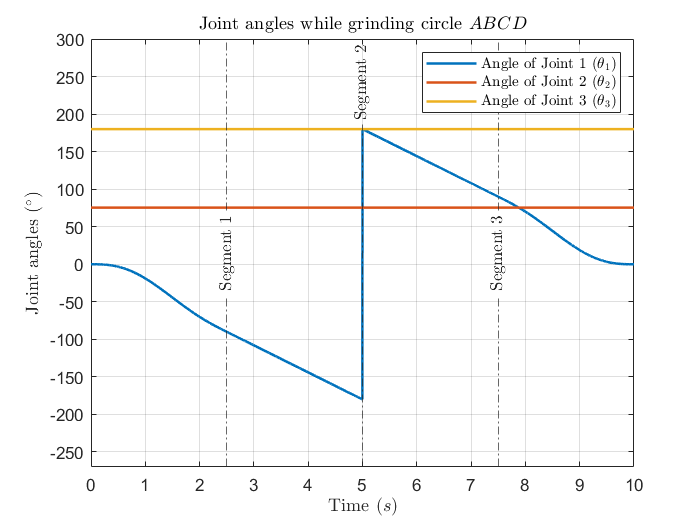

time = 0: time_total / 4e3: time_total; % 4001 steps for total time
% consecutive type for plotting
joint_angles = cell2mat(joint_angles_segs);
joint_angles = rad2deg(wrapToPi(joint_angles)); % conversion
joint_rates = cell2mat(joint_rates_segs);
joint_rates = rad2deg(joint_rates); % conversion

% plot joint angles versus time
figure
plot(time, joint_angles, 'LineWidth', 1.5)
axis([0, 10, -270, 300]); grid on
title('Joint angles while grinding circle $ABCD$', 'interpreter', 'latex')
xlabel('Time ($s$)', 'interpreter', 'latex')
ylabel('Joint angles ($^{\circ}$)', 'interpreter', 'latex')
legend('Angle of Joint 1 ($\theta_1$)', 'Angle of Joint 2 ($\theta_2$)',...
       'Angle of Joint 3 ($\theta_3$)', 'interpreter', 'latex')
for i = 1: 3
    xl = xline(time_total * i / 4, '-.', sprintf('Segment %d', i), ...
               'HandleVisibility','off', 'interpreter', 'latex');
    xl.LabelHorizontalAlignment = 'center';
    if i ~= 2
        xl.LabelVerticalAlignment = 'middle';
    end
end

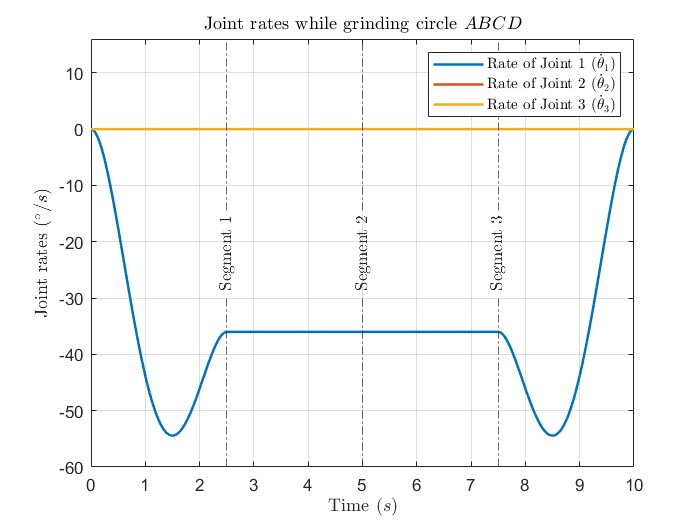

% plot joint rates versus time
figure
plot(time, joint_rates, 'LineWidth', 1.5)
axis([0, 10, -60, 16]); grid on
title('Joint rates while grinding circle $ABCD$', 'interpreter', 'latex')
xlabel('Time ($s$)', 'interpreter', 'latex')
ylabel('Joint rates ($^{\circ}/s$)', 'interpreter', 'latex')
legend('Rate of Joint 1 ($\dot{\theta}_1$)', 'Rate of Joint 2 ($\dot{\theta}_2$)',...
       'Rate of Joint 3 ($\dot{\theta}_3$)', 'interpreter', 'latex')
for i = 1: 3
    xl = xline(time_total * i / 4, '-.', sprintf('Segment %d', i), ...
               'HandleVisibility','off', 'interpreter', 'latex');
    xl.LabelHorizontalAlignment = 'center';
    xl.LabelVerticalAlignment = 'middle';
end

We can see from the figure of joint angles that the quintic polynomial is able to interpolate between any endpoint position and velocity requirements.

For $\theta_1$, segment 1 and 4 are smooth curves while segment 2 and 3 are like line segments because the endpoint velocities are equal. Also, there is a sharp increase between segments 2 and 3 as a result of the angle wrapping. Joint 1 should be continuously rotating clockwise about $z_0$ axis in reality.

For $\theta_2$ and $\theta_3$, the resulting angles in the trajectory remain unchanged because equal angles have been assigned in the waypoints. This further proves the flexibility of trajectory planning using polynomials.

From the figure of joint rates, we can see that $\dot{\theta}_1$ has an overshoot at the beginning which goes to constant speed in the following segments and returns symmetrically to zero velocity. $\dot{\theta}_2$ and $\dot{\theta}_3$ remain zero during the operation.

We can also obtain the path of the tool tip using the joint angles and the forward kinematics as computed. By substituing $\theta$ into $^0_AT$, we get the $3\times1$ position of point A in frame $O_0$:

% this segment is time-consuming. Don't run together with other segs
pos_A_segs = cell(1, 4); % position of point A in each seg
for i = 1: 4
    pos_A_segs{i} = zeros(3, length(joint_angles_segs{i}));
    for j = 1: length(joint_angles_segs{i})
        % position from inverse kinematics
        pos_A_segs{i}(:, j) = vpa( ...
            subs(T_A{4}(1: 3, 4), t, joint_angles_segs{i}(:, j)));
    end
end

Then we can plot the path of the tooltip on the work surface, both in 2D space which only considers the x and y coordinates and in 3D space which considers the z coordinate as well.

Based on our assumptions, to project the coordinates in frame $O_0$ on the working surface as shown, the x and y coordinates need to be reversed. Also, the z coordinates will be subtracted by that of the way points to move the z coordinate of the plane to 0.

Different segments are plotted with different colors for better identification, and the positions of the points are also marked. Also, an identical reference circle as the desired grinding path is drawn on the figures for comparison.

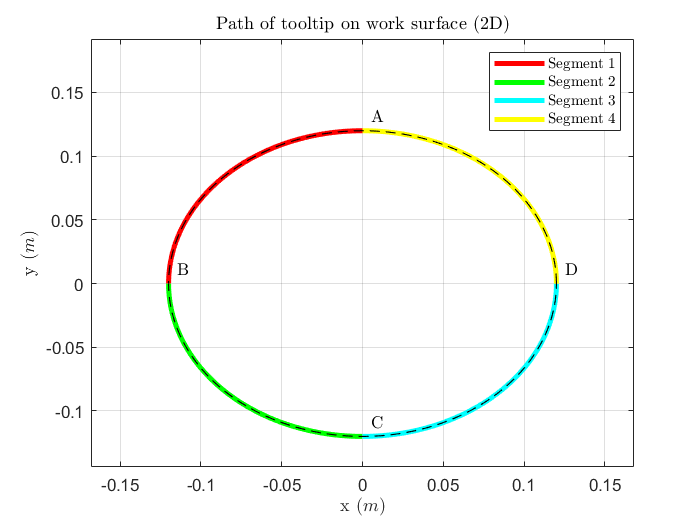

% plot in 2D space using only x y coordinates
figure
color = 'rgcy';

for i = 1: 4
    plot(pos_A_segs{i}(2, :), pos_A_segs{i}(1, :), ... % reverse x and y
         sprintf('%s', color(i)), 'LineWidth', 3)
    hold on
end
axis([-r_pts*1.4, r_pts*1.4, -r_pts*1.2, r_pts*1.6]); grid on
title('Path of tooltip on work surface (2D)', 'interpreter', 'latex')
xlabel('x ($m$)', 'interpreter', 'latex')
ylabel('y ($m$)', 'interpreter', 'latex')
legend('Segment 1', 'Segment 2', 'Segment 3', 'Segment 4', 'interpreter', 'latex')
% reference circle
viscircles([0, 0], r_pts, 'Color', 'k', 'LineStyle', '--', 'LineWidth', 0.7, ...
           'EnhanceVisibility', false);
% points ABCD
for i = 1: 4
    text(pts_xy(2, i)+5e-3, pts_xy(1, i)+0.01, ... % also change coordinate
         sprintf('%s', pt_names(i)), 'interpreter', 'latex')
end

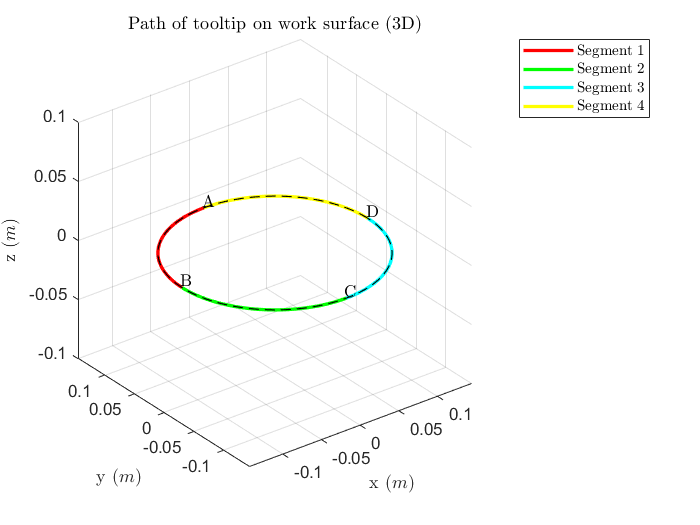

% plot in 3D space using x, y and z coordinates
figure
color = 'rgcy';
for i = 1: 4
    plot3(pos_A_segs{i}(2, :), pos_A_segs{i}(1, :), ...
          way_pts(3, i) - pos_A_segs{i}(3, :), ... % reverse x y and subtract z
          sprintf('%s', color(i)), 'LineWidth', 2)
    hold on
end
axis([-r_pts*1.2, r_pts*1.2, -r_pts*1.2, r_pts*1.2, -0.1, 0.1]); grid on
title('Path of tooltip on work surface (3D)', 'interpreter', 'latex')
xlabel('x ($m$)', 'interpreter', 'latex')
ylabel('y ($m$)', 'interpreter', 'latex')
zlabel('z ($m$)', 'interpreter', 'latex')
legend('Segment 1', 'Segment 2', 'Segment 3', 'Segment 4', 'interpreter', 'latex')
% reference circle
viscircles([0, 0], r_pts, 'Color', 'k', 'LineStyle', '--', 'LineWidth', 0.7, ...
           'EnhanceVisibility', false);
% points ABCD
for i = 1: 4
    text(way_pts(2, i)+5e-3, way_pts(1, i)+0.01, 0, ... % change coordinate
         sprintf('%s', pt_names(i)), 'interpreter', 'latex')
end

We can easily see from the figures that not only the path fits well with the desired trajectory on the working plane but also its z coordinate remains unchanged during the operation.

In fact, according to the structure of the robot, joint 1 is the only joint that needs to move during the grinding of a circle while the other two are static. Therefore, it is easy for the robot to perfectly follow a circular trajectory in which case the desired position is not only achieved at via points but also at any point on the trajectory. Also, the number of waypoints selected from the path will also have no influence on the tracking accuracy.

As for the respective joint torques versus time, we need to make some more assumptions:

- Only three forces and torques will be acting on the tooltip during grinding: the grinding torque $N_{x3}$, the supporting force $f_N$, and the friction force $f_t$. The direction of grinding torque $N_{x3}$ will always be parallel to $x_3$ axis, while the direction of $f_t$ will always be against the marching direction of tooltip A and $f_N$ will be perpendicular to the working surface. The magnitudes of $N_{x3}$, $f_N$ and $f_t$ are constant which are $0.04Nm$, $0.4N$ and $0.4N$ respectively.

- As the robot is moving at a constant speed most of the time, and assume the weight of the structures are light enough such that the dynamic driving force is much less than the interaction forces and torques, the joint torques required for the link dynamics can be ignored and the joint torques will be computed only based on the equivalent joint torques principles.

As derived before, we need to obtain the expressions of external forces and torque in frame $O_0$ for the calculation. First we can use


$$^0N_{x3}=0.04Nm\;\cdot\;^0x_3$$



$$^0f_N=0.4N\cdot(-\;^0z_0)$$


and compute $^0f_t$ according to the tangent of the circular path. Then

$\left\lbrace \begin{array}{ll} ^0F=^0f_N\;+\;^0f_t \\ ^0N=^0N_{x3} \end{array}$.

% this segment is also time-consuming
N_x3_0 = 0.04 * T{4}(1: 3, 1)

$$N\_x3\_0 = \left(\begin{array}{c} \frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{25}-\frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{25}\\ \frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{25}+\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{25}\\ -\frac{\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)}{25} \end{array}\right)$$

f_N_0 = 0.4 * [0 0 -1]'

f_N_0 =          0
         0
   -0.4000


joint_angles = cell2mat(joint_angles_segs); % re-generation of angles in radius
F_0_part = zeros(6, 4001);
for i = 1: 4001
    F_0_part(:, i) = subs([f_N_0; N_x3_0], t, joint_angles(:, i));
end
% calculate instantaneous f_t_0
pos_A = cell2mat(pos_A_segs);
pos_A_xy = pos_A(1: 2, :);
f_t_0 = [-pos_A_xy(2, :); pos_A_xy(1, :)] ./ vecnorm(pos_A_xy) * 0.4; % direction is [-y, x]; value is 4
f_t_0 = [f_t_0; zeros(1, 4001)];
% full F_0
F_0 = F_0_part;
F_0(1: 3, :) = F_0(1: 3, :) + f_t_0;

After that, we substitude into the previously derived joint torques:

% a more time-consuming segment
tau_0 = zeros(3, 4001);
tau_0_A = zeros(3, 4001); % for comparison of methods
for i = 1: 4001
    % substitude F and theta into torque formula
    tau_0(:, i) = subs(subs(tau_0_1, F, F_0(:, i)), t, joint_angles(:, i));
    tau_0_A(:, i) = subs(subs(tau_0_2, F, F_0(:, i)), t, joint_angles(:, i));
end

Do plotting using the joint torques obtained:

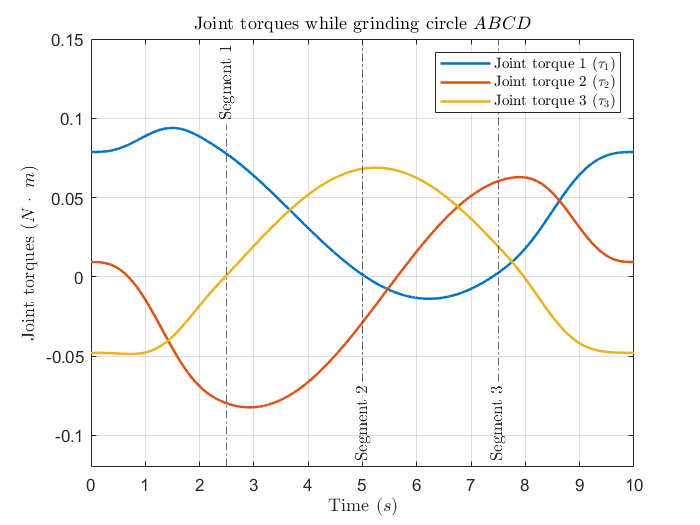

figure
plot(time, tau_0, 'LineWidth', 1.5)
axis([0, 10, -0.12, 0.15]); grid on
title('Joint torques while grinding circle $ABCD$', 'interpreter', 'latex')
xlabel('Time ($s$)', 'interpreter', 'latex')
ylabel('Joint torques ($N\cdot\;m$)', 'interpreter', 'latex')
legend('Joint torque 1 ($\tau_1$)', 'Joint torque 2 ($\tau_2$)', ...
       'Joint torque 3 ($\tau_3$)', 'interpreter', 'latex')
for i = 1: 3
    xl = xline(time_total * i / 4, '-.', sprintf('Segment %d', i), ...
               'HandleVisibility','off', 'interpreter', 'latex');
    xl.LabelHorizontalAlignment = 'center';
    if i ~= 1
        xl.LabelVerticalAlignment = 'bottom';
    end
end

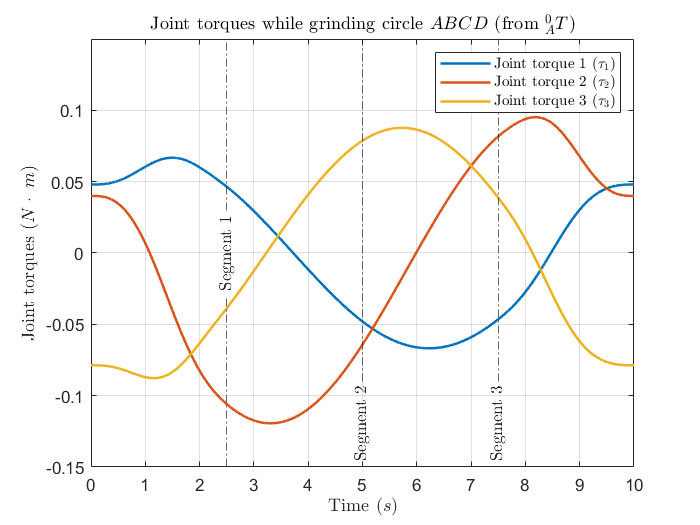

% for comparison
figure
plot(time, tau_0_A, 'LineWidth', 1.5)
axis([0, 10, -0.15, 0.15]); grid on
title('Joint torques while grinding circle $ABCD$ (from $^0_AT$)', 'interpreter', 'latex')
xlabel('Time ($s$)', 'interpreter', 'latex')
ylabel('Joint torques ($N\cdot\;m$)', 'interpreter', 'latex')
legend('Joint torque 1 ($\tau_1$)', 'Joint torque 2 ($\tau_2$)', ...
       'Joint torque 3 ($\tau_3$)', 'interpreter', 'latex')
for i = 1: 3
    xl = xline(time_total * i / 4, '-.', sprintf('Segment %d', i), ...
               'HandleVisibility','off', 'interpreter', 'latex');
    xl.LabelHorizontalAlignment = 'center';
    if i == 1
        xl.LabelVerticalAlignment = 'middle';
    else
        xl.LabelVerticalAlignment = 'bottom';
    end
end

From the plots we see that the torque computed from different Jacobians are also slightly different, while the first one should be correct. Through comparison, we can also know about the influence of the existance of endpoint force on the joint torques.

Testing segment: alternative method, compute directly using the force and Jacobian expressed in frame A:

tau_A = J_E.' * F_n1

$$tau\_A = \begin{array}{l} \left(\begin{array}{c} f_{x}\,\left(\frac{\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}+\frac{3\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}+\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{10}\right)-f_{y}\,\left(\frac{3\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{20}-\frac{\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}+\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10}\right)-N_{z}\\ f_{z}\,\left(\frac{3\,\sin\left(\theta_{2}\right)}{20}+\frac{\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{10}\right)-N_{y}\,\cos\left(\theta_{1}\right)+N_{x}\,\sin\left(\theta_{1}\right)-\frac{f_{x}\,\cos\left(\theta_{1}\right)\,\sigma_{1}}{20}-\frac{f_{y}\,\sin\left(\theta_{1}\right)\,\sigma_{1}}{20}\\ f_{x}\,\left(\frac{\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{10}+\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{10}\right)-f_{y}\,\left(\frac{\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)}{10}-\frac{\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{10}\right)-N_{z}\,\cos\left(\theta_{2}\right)-N_{x}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-N_{y}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\frac{f_{z}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,\cos\left(\theta_{2}\right)-2\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

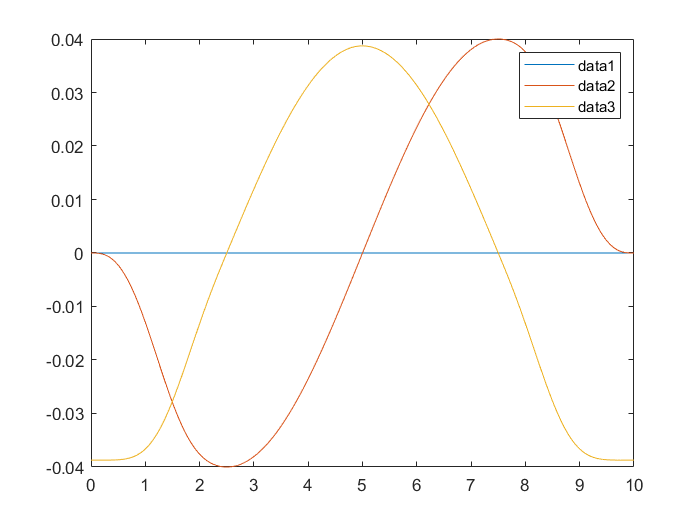

F_A = [zeros(3, 4001)
       0.04 * ones(1, 4001)
       zeros(2, 4001)];
tau_A1 = zeros(3, 4001);
for i = 1: 4001
    tau_A1(:, i) = subs(subs(tau_A, t, joint_angles(:, i)), F, F_A(:, i));
end
plot(time, tau_A1)
legend()

This plot is almost the same with previous when taking the forces as zero. In this case the torques calculated by the two methods will also be similar. This shows my solution should be correct but I wonder why the torque is not constant.

The case that $f_N$ and $f_t$ are zero can be included in report because this might be compared with the standard solutions.

This is the end of solution for Q3, and while I have documented most of my thinkings in this file, some further analysis might also be done in the report.

The complete 'program' as required is also exported into another file.

Function definitions:

function x_hat = hat_map(x)
% The function that transfers a 3x1 vector to a skew-symmetric matrix
    x_hat = [    0 -x(3)  x(2)
              x(3)     0 -x(1)
             -x(2)  x(1)     0];
end

function [t, p] = inv_kin(pxy)
% exported inverse kinematics function
% input:  x and y coordinates of endpoint position
% output: computed joint variables and the 3x1 endpoint position
    p = [pxy; sqrt(0.15^2 + 0.1^2 - sum(pxy.^2)) + 2/5]; % compute z coordinate in workspace
    v_o1_a = p - [0, 0, 2/5]';
    v1 = cross(v_o1_a, [1, 0, 0]'); % vectors a and b
    if v1 == [0, 0, 0]'
        v1 = cross(v_o1_a, [0, 1, 0]');
    end
    v1 = v1 / norm(v1);
    v2 = cross(v_o1_a, v1);
    v2 = v2 / norm(v2);
    pc = p - 4 / 13 * v_o1_a; % centre
    r = 0.15 * 0.1 / norm([0.15, 0.1]); % radius
    if v2(3) == 0 % obtain the minimized PBz
        alpha = pi / 2 * sign(v1(3));
        phi = 1.5 * pi - alpha;
    else
        alpha = atan(v1(3) / v2(3));
        if v2(3) > 0
            phi = 1.5 * pi - alpha;
        else
            phi = pi / 2 - alpha;
        end
    end
    pB = pc + r * cos(phi) * v1 + r * sin(phi) * v2;
    % solve inverse kinematics
    t_2 = acos((20 * pB(3) - 8) / 3); % keep +ve soln
    if sin(t_2) == 0
        t_1 = 0;
    else
        t_1 = atan2(20 * pB(2) / (3 * sin(t_2)), 20 * pB(1) / (3 * sin(t_2)));
    end
    t_3 = atan2(10 * (p(2) * cos(t_1) - p(1) * sin(t_1)), ...
                4 * sin(t_2) + 10 * (p(1) * cos(t_1) .* cos(t_2) + ...
                                     p(2) * sin(t_1) .* cos(t_2) - ...
                                     p(3) * sin(t_2)));
    t = [t_1 t_2 t_3]';
end

function [posi, velo] = poly_5th_and_4th(t, paras)
% function that returns an array of polynomial and its derivative
% according to parameters
    posi = paras(1) + paras(2) * t + paras(3) * t .^ 2 +...
           paras(4) * t .^ 3 + paras(5) * t .^ 4 + paras(6) * t .^ 5;
    velo = paras(2) + 2 * paras(3) * t + 3 * paras(4) * t .^ 2 +...
           4 * paras(5) * t .^ 3 + 5 * paras(6) * t .^ 4;
end